clc; clear all; close all;

A =[0 1 2; -4 -2.3 4.5 ;0 -5 -1.4]

A =          0    1.0000    2.0000
   -4.0000   -2.3000    4.5000
         0   -5.0000   -1.4000


B=[2 3;
    0 1;
    -1 -2]; 
C=[0 1 0;0 0 0;0 0 0]

C =      0     1     0
     0     0     0
     0     0     0


D=0;

% Parámetros del MPC
Ts = 0.1;         % Tiempo de muestreo
N = 20;            % Horizonte de predicción
Qy = diag([100;1000;100])       % Penalización de la salida

Qy =          100           0           0
           0        1000           0
           0           0         100


R = diag([0.001;0.001])          % Penalización del control

R = 1.0e-03 *

    1.0000         0
         0    1.0000


yref = [1;0;0]         % Referencia deseada

yref =      1
     0
     0


x0 = [0;0;1];      % Estado inicial
Qf = 1000*Qy;  
Qy = diag([100;1000;100]) 

Qy =          100           0           0
           0        1000           0
           0           0         100






% Llamada a la función MPC
[X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0, Qf);

nu = 2

Qbig =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

Qbig = 1.0e+05 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

q =      0
  -100
     0
     0
  -100
     0
     0
  -100
     0
     0


Xmin =      0
   -10
     0


Umax =      1
    10


Umin =     -1
   -10


Aineq =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     

bineq =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =    -0.9285
    0.3964
    1.5097
   -0.0786
    1.0207
    0.6303
   -0.4220
    0.9994
    0.3860
   -0.6875


X

X =    -0.9285   -0.0786   -0.4220   -0.6875   -0.9612   -1.2306   -1.4972   -1.7608   -2.0215   -2.2794   -2.5345   -2.7868   -3.0365   -3.2835   -3.5279   -3.7699   -4.0087   -4.2503   -4.4455   -5.0089
    0.3964    1.0207    0.9994    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.5097    0.6303    0.3860    0.1078   -0.1626   -0.4306   -0.6958   -0.9582   -1.2179   -1.4750   -1.7294   -1.9813   -2.2307   -2.4777   -2.7222   -2.9644   -3.2046   -3.4393   -3.7008   -3.7142


U

U =    -1.0000    1.0000   -1.0000   -0.5894   -0.5790   -0.4765   -0.3865   -0.2975   -0.2106   -0.1259   -0.0432    0.0375    0.1161    0.1927    0.2674    0.3399    0.4111    0.4757    0.5775    0.3480
   -3.3318    1.1817   -1.1501   -0.9881   -0.8396   -0.7143   -0.5870   -0.4607   -0.3349   -0.2097   -0.0850    0.0391    0.1627    0.2859    0.4086    0.5306    0.6543    0.7607    1.0119    0.0344


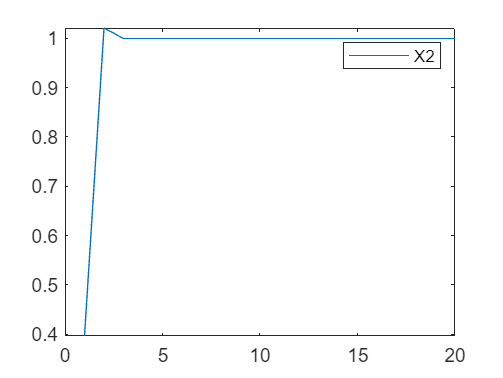


plot(X(2,:)); 
legend('X2')


plot(U(1,:));  

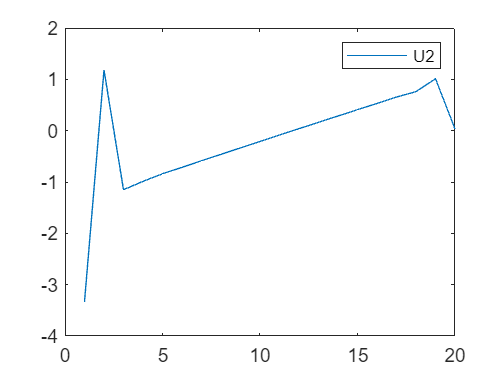

legend('U1')

plot(U(2,:))
legend('U2')

function [X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yrefk, x0, Qf, constraints)
    % Convertir sistema continuo a discreto (ZOH)
    sysc = ss(A, B, C, D);
    sysd = c2d(sysc, Ts, 'zoh');
    Ad = sysd.A;
    Bd = sysd.B;
    
    % Dimensiones del sistema
    nx = size(A, 1); % Número de estados
    nu = size(B, 2) % Número de entradas (MIMO)
    ny = size(C, 1); % Número de salidas (MIMO)

    % Función de costo
    Qbig = blkdiag(kron(eye(N), C' * Qy * C), kron(eye(N), R))
    Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx))=C'*Qy*C+C'*Qf*C
    
    % Asegurar que yrefk tenga dimensiones correctas
    if size(yrefk, 2) ~= 1
        error('yrefk debe ser un vector columna de tamaño (ny, 1)')
    end
    q = -[repmat(C' * Qy * yrefk, N, 1); zeros(N*nu, 1)];
    q(nx*(N-1)+(1:nx),1)=-C'*Qy*yrefk-C'*Qf*yrefk
    
    % Restricciones de igualdad 

    Aeq = zeros(N * nx, N * (nx + nu));
    beq = zeros(N * nx, 1);

    for k = 1:N
        Aeq((k-1)*nx+1:k*nx, (k-1)*nx+1:k*nx) = -eye(nx);
        if k == 1
            Aeq(1:nx, 1:nx) = -eye(nx);
            Aeq(1:nx, nx*N+1:nx*N+nu) = Bd;
            beq(1:nx) = -Ad * x0;
        else
            Aeq((k-1)*nx+1:k*nx, (k-2)*nx+1:(k-1)*nx) = Ad;
            Aeq((k-1)*nx+1:k*nx, nx*N+(k-1)*nu+1:nx*N+k*nu) = Bd;
        end
    end


    % Restricciones de control y estados
    Aineq = [];
    bineq = [];

    Xmax = [0;10;0];
    Xmin = [0;-10;0]

   Umax = [1;10]
   Umin = [-1;-10] %----> NaN o []
   [Aineq, bineq] = restricciones(nx, nu, N,Xmin,Xmax, Umin, Umax)


  
    % Resolver el problema de optimización cuadrática
    z = quadprog(Qbig, q, Aineq, bineq, Aeq, beq)

    % Extraer X y U
    X = reshape(z(1:nx*N), nx, N);
    U = reshape(z(nx*N+1:end), nu, N);
end

function [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax)
    nvar = nx * N + nu * N;
    
    Aineq = [];
    bineq = [];
    
    %% Restricciones para los estados
    for t = 1:N
        for i = 1:nx
            idx = (t-1)*nx + i; 
            if ~isempty(Xmax)
                if ~( Xmax(i)==0 && ~isempty(Xmin) && Xmin(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Xmax(i)];
                end
            end

            if ~isempty(Xmin)
                if ~( Xmin(i)==0 && ~isempty(Xmax) && Xmax(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Xmin(i)];
                end
            end
        end
    end
    
    %% Restricciones para las entradas
    for t = 1:N
        for j = 1:nu
            idx = nx * N + (t-1)*nu + j; 
            if ~isempty(Umax)
                if ~( Umax(j)==0 && ~isempty(Umin) && Umin(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Umax(j)];
                end
            end
            
            if ~isempty(Umin)
                if ~( Umin(j)==0 && ~isempty(Umax) && Umax(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Umin(j)];
                end
            end
        end
    end
end

